clear;
close all;
clc;
opts = bodeoptions('cstprefs');
opts.FreqUnits = 'Hz';

s = tf('s');
fpwm = 3800;


### 400V scenario trafo un Leitdrive connesso ad una linea a 250kVA

Pnom = 250e3; % potenza nominale apparente trafo di media: 20kV/400V 250 kVA
Unom = 400;
fnom = 50;
Inom = Pnom/sqrt(3)/Unom;
Ucc = 0.06; % tensione di corto circuito, dato di targa
L2 = Ucc * Unom/sqrt(3)/Inom/(2*pi*fnom) % calcolo della induttanza dispersa trafo

L2 = 1.2223e-04

RL2 = 0.02 * Pnom/3/Inom^2

RL2 = 0.0128

### dato filtro attuale 400V

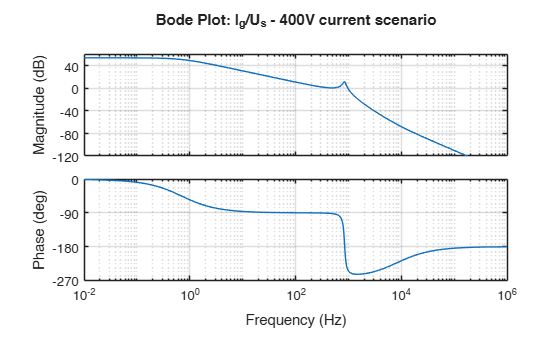

L1 = 330e-6;
RL1 = 2e-3;
RC = 50e-3;
C = 400e-6;

% Laplace transform
ZL1 = s*L1 + RL1;
ZRC = RC + 1/s/C;
ZL2 = s*L2;

% Transfer function
H_ig_us = minreal(1/(ZL2*(1+ZL1/ZL2+ZL1/ZRC)));
figure; % bode(H_ig_us, opts); grid on
h = bodeplot(H_ig_us, opts);
grid on
title('Bode Plot: I_g/U_s - 400V current scenario')


% Find peaks of the transfer function
w = logspace(1,5,10000);
H = squeeze(freqresp(H_ig_us,w));
mag = 20*log10(abs(H));
idx = find( mag(2:end-1) > mag(1:end-2) & ...
    mag(2:end-1) > mag(3:end) ) + 1;
[~,k] = max(mag(idx));
fr = w(idx(k))/(2*pi);
peak = mag(idx(k));
fprintf("Peak = %.2f dB\n",peak)

Peak = 11.99 dB


fprintf("fr = %.2f Hz\n",fr)

fr = 838.09 Hz



% --- Theoretical analysis ---
% poli del denominatore
den = [L1*L2*C, (L1+L2)*RC*C, (L1+L2), 0];
poli = roots(den);
sigma = -real(poli);
omega = abs(imag(poli));

freq_nat = sqrt(sigma(2)^2 + omega(2)^2) % Natural frequency

freq_nat = 5.2942e+03

freq_res = freq_nat / (2*pi)             % Resonance frequency

freq_res = 842.6023

damping_factor = sigma(2)/freq_nat

damping_factor = 0.0529


fprintf("Check: %.2fHz < %.2fHz < %.2fHz \n", 10*50, freq_res, 0.3*fpwm)

Check: 500.00Hz < 842.60Hz < 1140.00Hz 


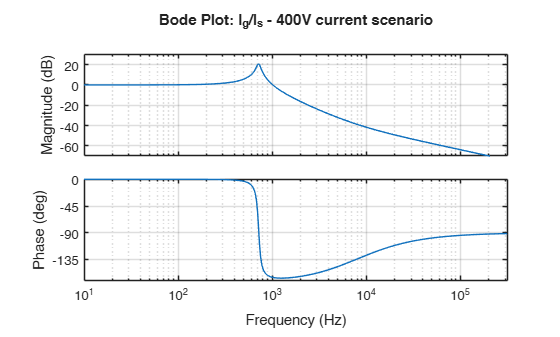


%fres = 1/(2*pi*sqrt(C*L2)) % frequenza di risonanza tra il banco di condensatori del filtro LC e la leakage della linea
%f1 = fres
%f2 = fres*1.2;

% A_res = bode(H_ig_us,2*pi*fres)
% A_pwm = bode(H_ig_us,2*pi*fpwm)
% A_res_dB = 20*log10(Ares)
% A_pwm_dB = 20*log10(A_pwm)

% --- Transfer function ig/is ---
H_ig_is = minreal((1+s*RC*C)/(1+s*RC*C+s^2*L2*C));
figure; %bode(H_ig_is, opts); grid on
h = bodeplot(H_ig_is, opts);
grid on
title('Bode Plot: I_g/I_s - 400V current scenario')


% Find peaks of the transfer function
w = logspace(1,5,10000);
H = squeeze(freqresp(H_ig_is,w));
mag = 20*log10(abs(H));
idx = find( mag(2:end-1) > mag(1:end-2) & ...
    mag(2:end-1) > mag(3:end) ) + 1;
[~,k] = max(mag(idx));
fr = w(idx(k))/(2*pi);
peak = mag(idx(k));
fprintf("Peak = %.2f dB\n",peak)

Peak = 20.92 dB


fprintf("fr = %.2f Hz\n",fr)

fr = 718.60 Hz



% --- Theoretical analysis ---
% poli del denominatore
den = [L2*C, RC*C, 1, 0];
poli = roots(den);
sigma = -real(poli);
omega = abs(imag(poli));

freq_nat = sqrt(sigma(2)^2 + omega(2)^2) % Natural frequency

freq_nat = 4.5225e+03

freq_res = freq_nat / (2*pi)             % Resonance frequency

freq_res = 719.7795

damping_factor = sigma(2)/freq_nat

damping_factor = 0.0452


fprintf("Check: %.2fHz < %.2fHz < %.2fHz \n", 10*50, freq_res, 0.3*fpwm)

Check: 500.00Hz < 719.78Hz < 1140.00Hz 


### dato filtro 400V scenario 1

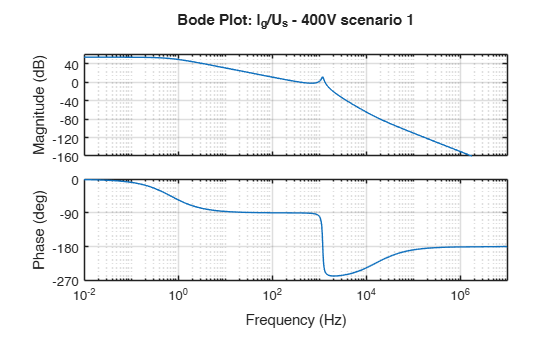

L1 = 330e-6;
RL1 = 2e-3;
RC = 50e-3;
C = 200e-6;

ZL1 = s*L1 + RL1;
ZRC = RC + 1/s/C;
ZL2 = s*L2;

% Transfer function
H_ig_us = minreal(1/(ZL2*(1+ZL1/ZL2+ZL1/ZRC)));
figure; %bode(H_ig_us, opts); grid on
h = bodeplot(H_ig_us, opts);
grid on
title('Bode Plot: I_g/U_s - 400V scenario 1')


% Find peaks of the transfer function
w = logspace(1,5,10000);
H = squeeze(freqresp(H_ig_us,w));
mag = 20*log10(abs(H));
idx = find( mag(2:end-1) > mag(1:end-2) & ...
    mag(2:end-1) > mag(3:end) ) + 1;
[~,k] = max(mag(idx));
fr = w(idx(k))/(2*pi);
peak = mag(idx(k));
fprintf("Peak = %.2f dB\n",peak)

Peak = 11.94 dB


fprintf("fr = %.2f Hz\n",fr)

fr = 1188.25 Hz



% Poli del denominatore
den = [L1*L2*C, (L1+L2)*RC*C, (L1+L2), 0];
poli = roots(den);
sigma = -real(poli);
omega = abs(imag(poli));

freq_nat = sqrt(sigma(2)^2 + omega(2)^2)

freq_nat = 7.4872e+03

freq_res = freq_nat / (2*pi)

freq_res = 1.1916e+03

damping_factor = sigma(2)/freq_nat

damping_factor = 0.0374


fprintf("Check: %.2fHz < %.2fHz < %.2fHz \n", 10*50, freq_res, 0.3*fpwm)

Check: 500.00Hz < 1191.62Hz < 1140.00Hz 


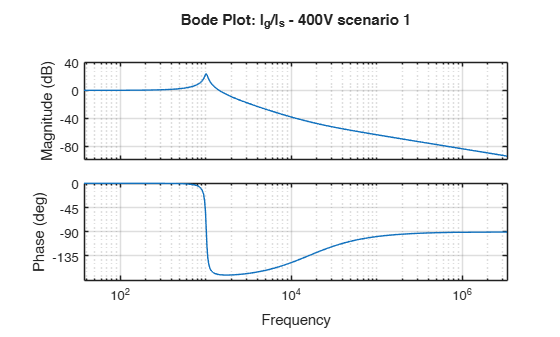


% --- Transfer function ig/is ---
H_ig_is = minreal((1+s*RC*C)/(1+s*RC*C+s^2*L2*C));
figure; %bode(H_ig_is, opts); grid on
h = bodeplot(H_ig_is, opts);
grid on
title('Bode Plot: I_g/I_s - 400V scenario 1')


% Find peaks of the transfer function
w = logspace(1,5,10000);
H = squeeze(freqresp(H_ig_is,w));
mag = 20*log10(abs(H));
idx = find( mag(2:end-1) > mag(1:end-2) & ...
    mag(2:end-1) > mag(3:end) ) + 1;
[~,k] = max(mag(idx));
fr = w(idx(k))/(2*pi);
peak = mag(idx(k));
fprintf("Peak = %.2f dB\n",peak)

Peak = 23.90 dB


fprintf("fr = %.2f Hz\n",fr)

fr = 1016.95 Hz



% --- Theoretical analysis ---
% poli del denominatore
den = [L2*C, RC*C, 1, 0];
poli = roots(den);
sigma = -real(poli);
omega = abs(imag(poli));

freq_nat = sqrt(sigma(2)^2 + omega(2)^2) % Natural frequency

freq_nat = 6.3958e+03

freq_res = freq_nat / (2*pi)             % Resonance frequency

freq_res = 1.0179e+03

damping_factor = sigma(2)/freq_nat

damping_factor = 0.0320


fprintf("Check: %.2fHz < %.2fHz < %.2fHz \n", 10*50, freq_res, 0.3*fpwm)

Check: 500.00Hz < 1017.92Hz < 1140.00Hz 
